im0 = imread('frames/5.jpg');
imp0 = imread('slides/ppt1.jpg');
imgray = rgb2gray(im0);

## Edge Detection

Using Sobel Operator we can take the derivative of the image.

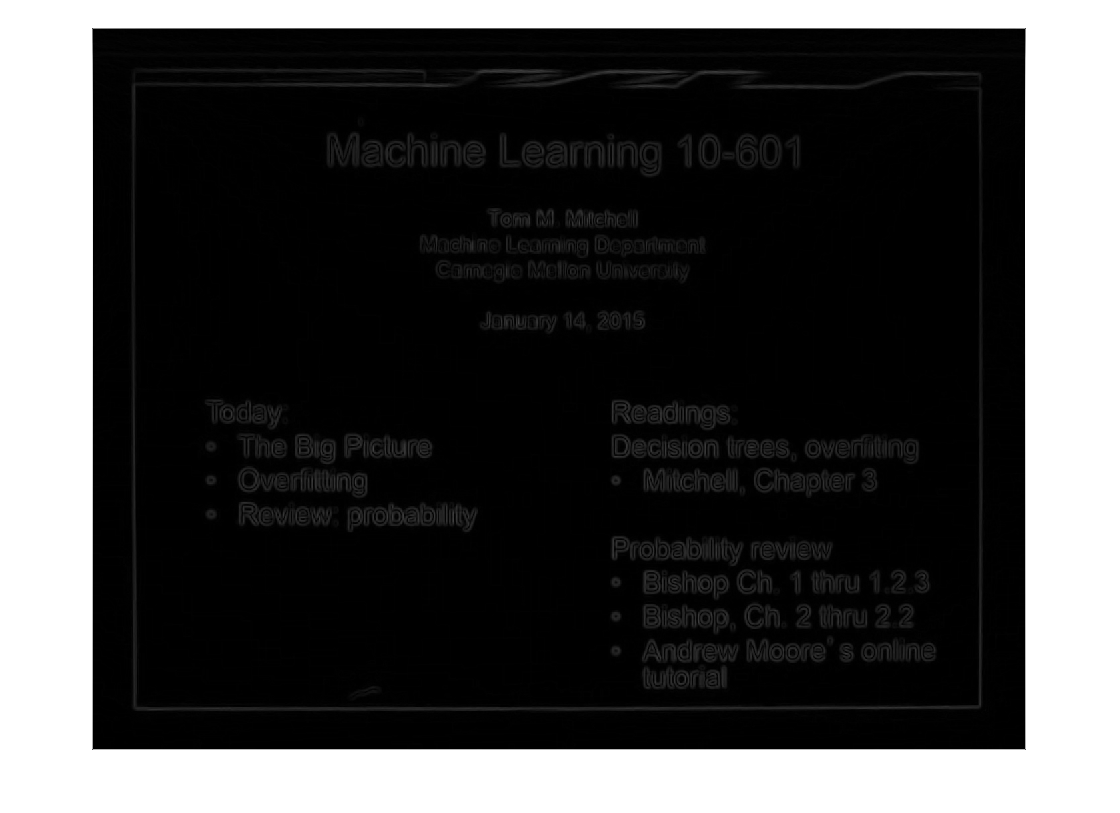

dx = conv2([-1 0 1; -2 0 2; -1 0 1], imgray);
dy = conv2([-1 -2 -1; 0 0 0; 1 2 1], imgray);
gradient = sqrt((dx.*dx) + (dy.*dy));
max_val = max(max(gradient));
min_val = min(min(gradient));
norm_gradient = uint8(round(255*(gradient-min_val)/(max_val-min_val)));
imshow(norm_gradient);

colsum = sum(double(norm_gradient));
rowsum = sum(double(norm_gradient), 2);
[val ,idx1] = max(colsum(4:698));
fprintf("First column: %f with value %f", idx, val);

First column: 481.000000 with value 26978.000000

[val ,idx2] = max(colsum(699:1394));
fprintf("Second column: %f with value %f", idx+699, val);

Second column: 1180.000000 with value 27071.000000

[val ,idx3] = max(rowsum(4:540));
fprintf("First row: %f with value %f", idx, val);

First row: 481.000000 with value 32099.000000

[val ,idx4] = max(rowsum(540:1076));
fprintf("Second row: %f with value %f", idx+540, val);

Second row: 1021.000000 with value 48094.000000

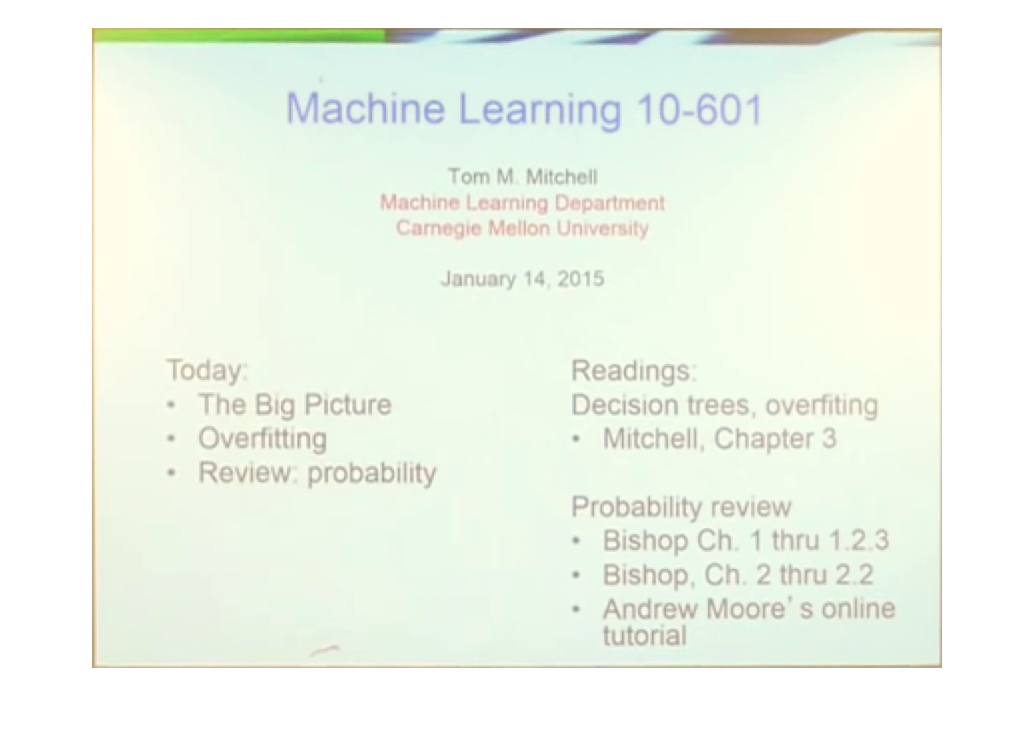

imshow(imcrop(im0, [idx1 idx3 idx2-idx1+699 idx4-idx3+540]));

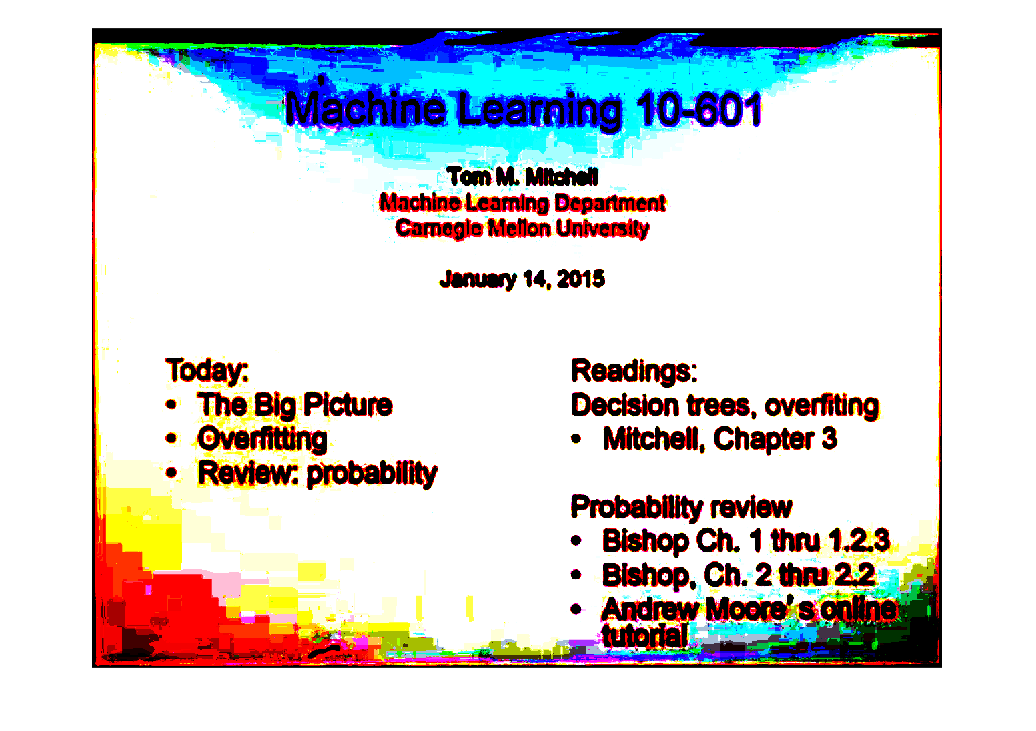

imshow(imhistmatch(imcrop(im0, [idx1 idx3 idx2-idx1+699 idx4-idx3+540]), imp0));